# **CP241 - Lab Assignment 3**

**Note: **Write your answers in the dedicated section only and submit this file as per instructions provided in the question paper.

**QUESTION-1(a) **

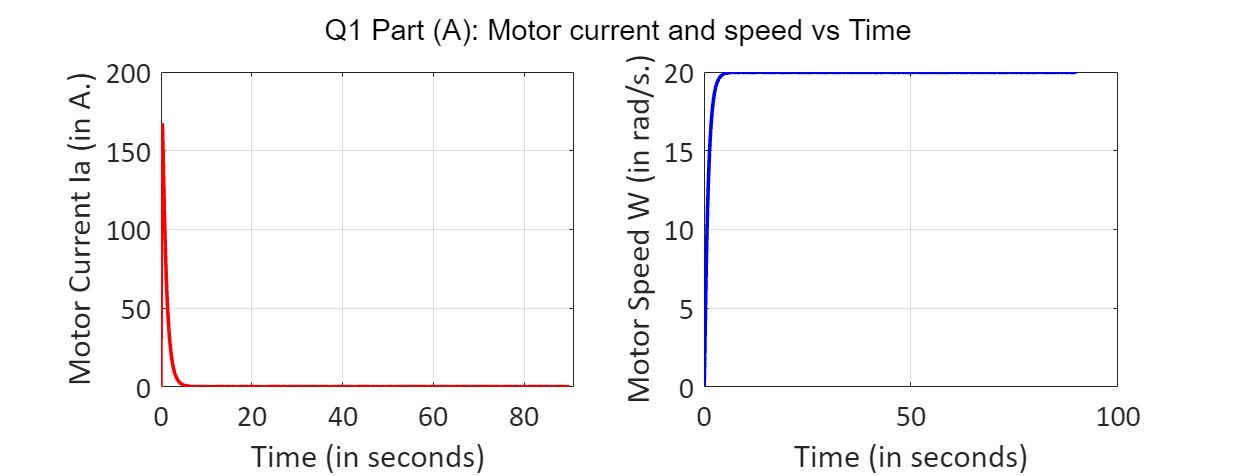

clear all
close all

q_part = "a";

% Declaring the constants
Ra=0.1;     % Ohms
La= 0.01;   % H
J=10;       % kgm^2
B=0.01;     % Nms
Kb=1;       % Vs/rad 
Kt=1;       % 1Nm/A
tspan= [0 90]; % given time span
x0 = [0;0];  % Initial conditions (current and speed)


% Writing the given equations inv form of LTI system state equation
%%%         X_dot = AX + BU ;               B_matrix (2x2)
% Where: X = [Current (x1) ; Speed (x2)] and U = [V_inp ; Tload]

A = [-Ra/La -Kb/La; Kt/J -B/J];
B_matrix = [1/La 0; 0 -1/J]; 

% Solving the state equation %
[t, states_part_a] = ode45(@(t,x)(A*x + B_matrix*[V_inp_q1(t, q_part) ; Tload_q1(t,q_part)]), tspan, x0);


%%% Plotting the respones / states %%%

fig1 = figure();
subplot(1,2,1);
plot(t,states_part_a(:,1),'r', 'LineWidth', 1.8);
xlabel('Time (in seconds)');
ylabel('Motor Current Ia (in A.)');
set(gca, 'FontName', 'Calibri', 'FontSize', 15);
xlim([0,91])
grid on
subplot(1,2,2)
plot(t,states_part_a(:,2),'b', 'LineWidth', 1.8);
xlabel('Time (in seconds)');
ylabel('Motor Speed W (in rad/s.)');
%xlim([0,91])
set(gca, 'FontName', 'Calibri', 'FontSize', 15);
sgtitle('Q1 Part (A): Motor current and speed vs Time')
fig1.Position = [10,10,1300,500];
set(gca, 'FontName', 'Calibri', 'FontSize', 15);
grid on;

**QUESTION-1(b)**

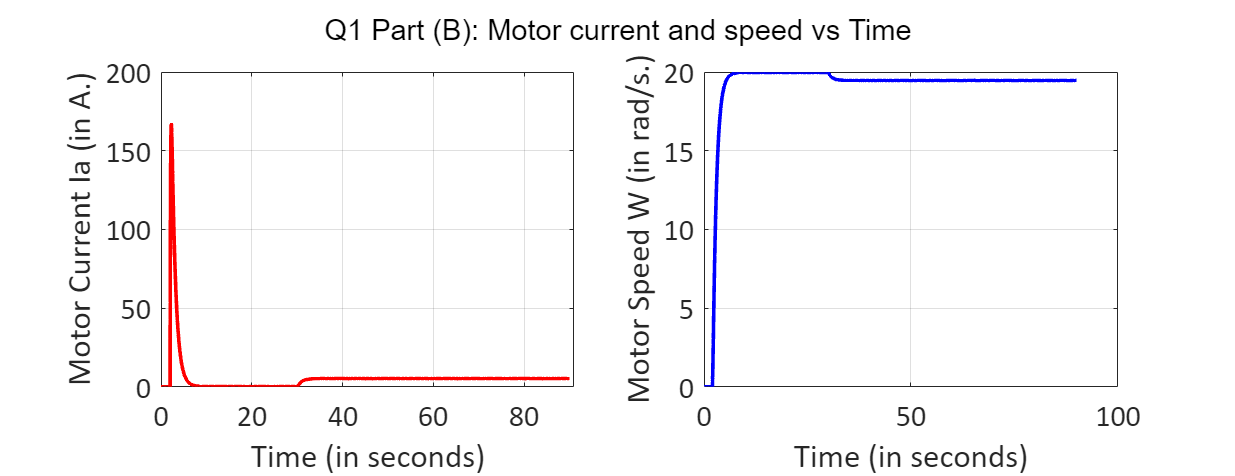

q_part = "b";

% Solving the dynamics %
[t, states_part_b] = ode45(@(t,x)(A*x + B_matrix*[V_inp_q1(t, q_part) ; Tload_q1(t,q_part)]), tspan, x0);

%%% Plotting the respones %%%
fig2 = figure();
subplot(1,2,1);
plot(t,states_part_b(:,1),'r', 'LineWidth', 1.8);
xlabel('Time (in seconds)');
ylabel('Motor Current Ia (in A.)');
set(gca, 'FontName', 'Calibri', 'FontSize', 15);
xlim([0,91])
grid on
subplot(1,2,2)
plot(t,states_part_b(:,2),'b', 'LineWidth', 1.8);
xlabel('Time (in seconds)');
ylabel('Motor Speed W (in rad/s.)');
set(gca, 'FontName', 'Calibri', 'FontSize', 15);
sgtitle('Q1 Part (B): Motor current and speed vs Time')
fig2.Position = [10,10,1300,500];
set(gca, 'FontName', 'Calibri', 'FontSize', 15);
grid on;

**QUESTION-1(c) **

% Equilibrium points of system without excitation
% Is same as solution to AX = 0

Eqbuilibrium_points = linsolve(A,[0;0])

Eqbuilibrium_points =      0
     0


Eigenvalues = eig(A)

Eigenvalues =    -8.8728
   -1.1282


**QUESTION-1(d) **

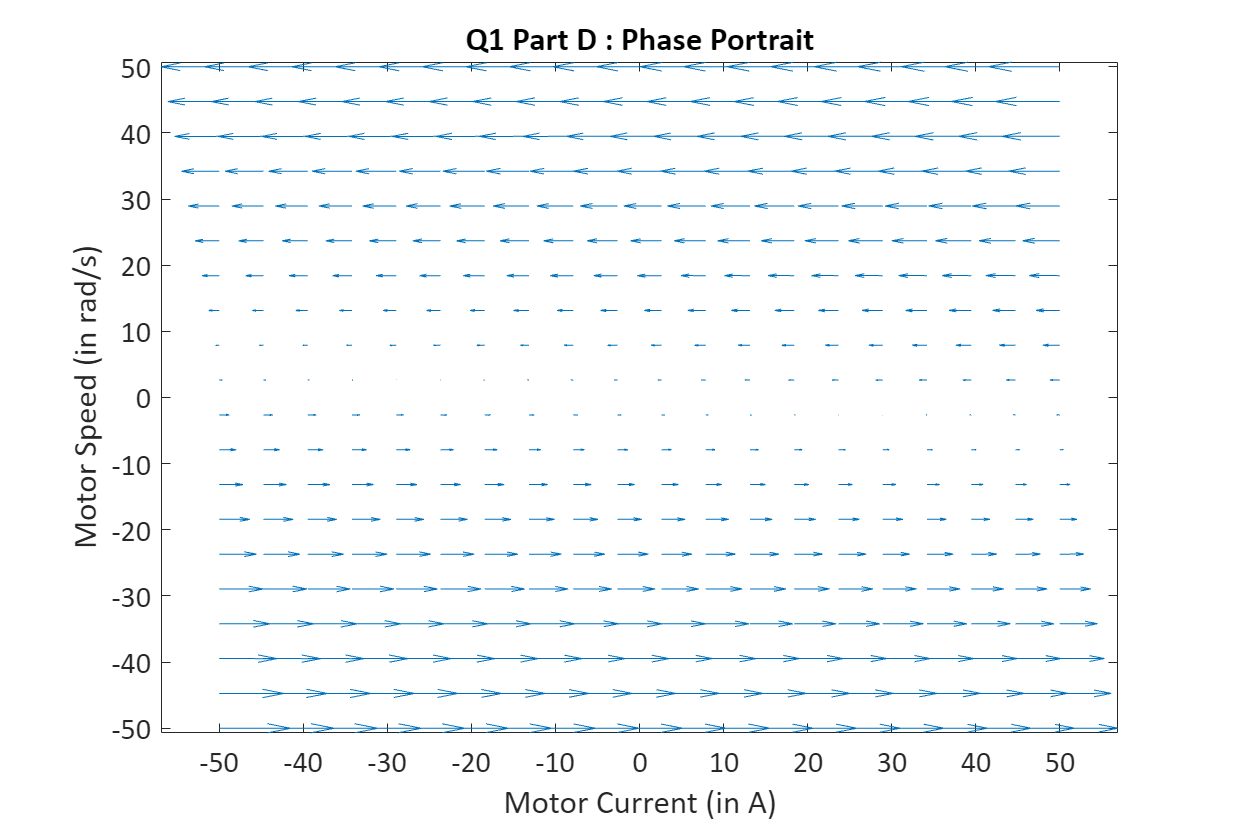

% Setting up the mesh %
step_size = 20 ;
[x1, x2] = meshgrid(linspace(-50, 50, step_size) , linspace(-50, 50, step_size));


% Finding the derivatives (x_dot) at each point of thw mesh %
x1_dot = A(1,1)*x1 + A(1,2)*x2;  %derivatives of state 1 (Motor Current Ia)
x2_dot = A(2,1)*x1 + A(2,2)*x2;  %derivatives of state 2 (Motor Speed W)

% Plotting the phase portrait %
fig3=figure();
quiver(x1,x2,x1_dot,x2_dot,1.2);
fig3.Position = [10,10,900,600];
title('Q1 Part D : Phase Portrait')
xlabel('Motor Current (in A)')
ylabel('Motor Speed (in rad/s)')
set(gca, 'FontName', 'Calibri', 'FontSize', 15);
axis tight

**QUESTION-2(a) epsilon=0**

epsilon = 0;
% Finding the equilibrium points using "solve" and symbolic vars
syms x_1 x_2;
x_1_dot = x_2;
x_2_dot = -x_1 + epsilon*x_2*(1-x_1^2);
dynamics = [x_1_dot, x_2_dot];
eqb_points = solve(dynamics == 0);
fprintf("Q2 Part(A) Epsilon = 0: \nEquilibrium points: (%0.1f, %0.1f)", eqb_points.x_1, eqb_points.x_2);

Q2 Part(A) Epsilon = 0: 
Equilibrium points: (0.0, 0.0)

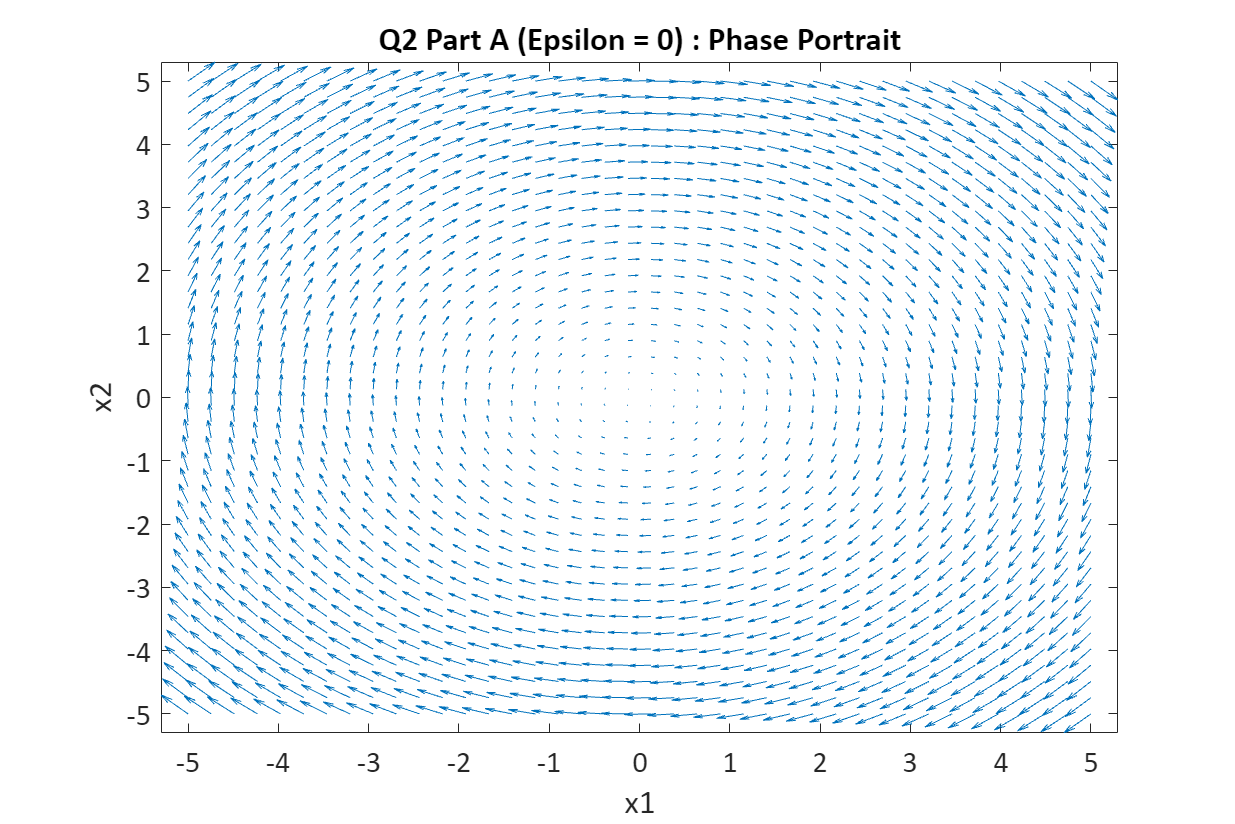


% Preparing the mesh for phase portrait
step_size = 40 ;
[x1, x2] = meshgrid(linspace(-5, 5, step_size) , linspace(-5, 5, step_size));

% Finding the derivatives of the states at each point of the mesh %
x1_dot_eps0 = x2;  %derivatives of state1 (x1_dot)
x2_dot_eps0 = -x1 + epsilon.*x2.*(1-x1.^2);  %derivatives of state2 (x2_dot)

% Plotting the phase portrait %
fig_q2_eps0=figure();
quiver(x1,x2,x1_dot_eps0,x2_dot_eps0,1.2);
fig_q2_eps0.Position = [10,10,900,600];
title('Q2 Part A (Epsilon = 0) : Phase Portrait')
xlabel('x1')
ylabel('x2')
set(gca, 'FontName', 'Calibri', 'FontSize', 15);
axis tight

fprintf("The trajectories forms concentric closed orbits  around the eqb point (origin).\nTherefore, the equilibrium point is a CENTER.")

The trajectories forms concentric closed orbits  around the eqb point (origin).
Therefore, the equilibrium point is a CENTER.

**QUESTION-2(a) epsilon=1**

epsilon = 1;

% Finding the equilibrium points using "solve" and symbolic vars
syms x_1 x_2;
x_1_dot = x_2;
x_2_dot = -x_1 + epsilon*x_2*(1-x_1^2);
dynamics = [x_1_dot, x_2_dot];
eqb_points = solve(dynamics == 0);
fprintf("Q2 Part(A) Epsilon = 1: \nEquilibrium points: (%0.1f, %0.1f)", eqb_points.x_1, eqb_points.x_2);

Q2 Part(A) Epsilon = 1: 
Equilibrium points: (0.0, 0.0)

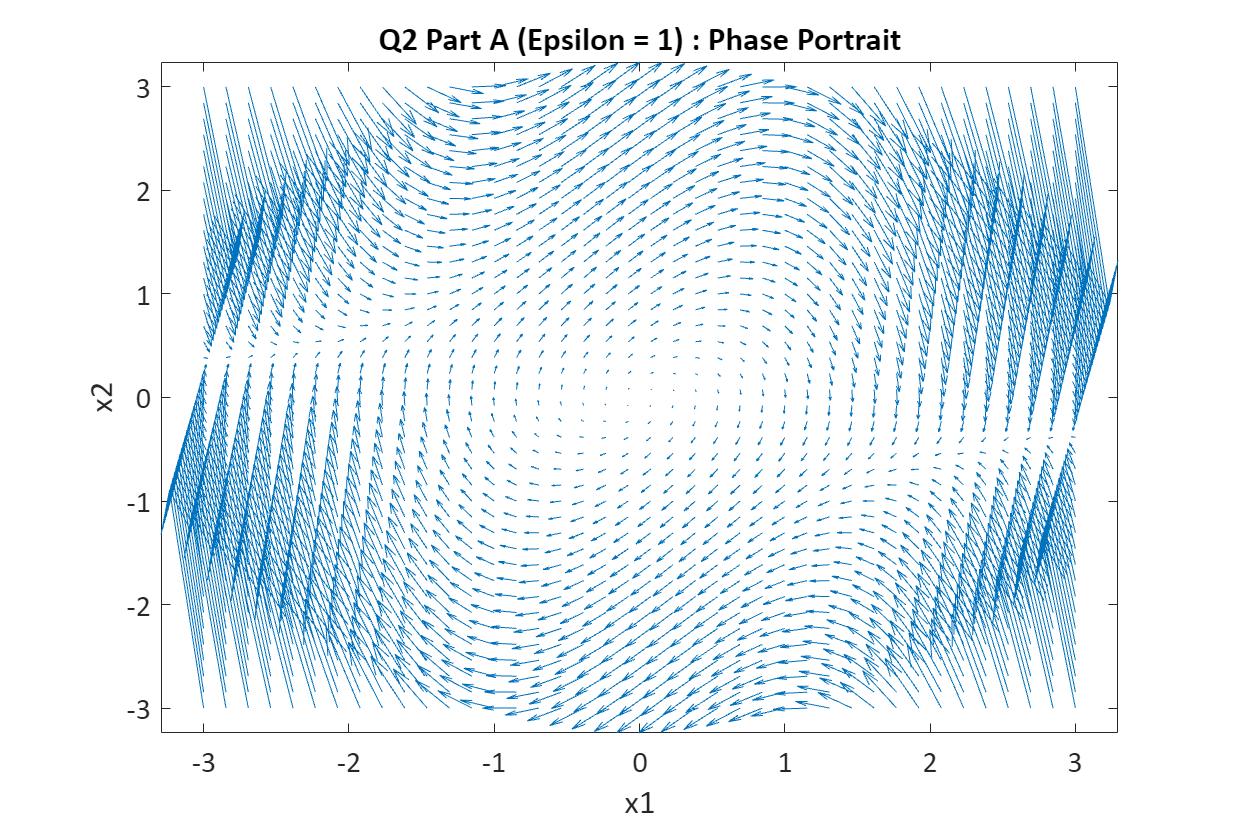


% Preparing the mesh for phase portrait
step_size = 40 ;
[x1, x2] = meshgrid(linspace(-3, 3, step_size) , linspace(-3, 3, step_size));

% Finding the derivatives of the states at each point of the mesh %
x1_dot_eps1 = x2;  %derivatives of state1 (x1_dot)
x2_dot_eps1 = -x1 + epsilon.*x2.*(1-x1.^2);  %derivatives of state2 (x2_dot)

% Plotting the phase portrait %
fig_q2_eps1 = figure();
quiver(x1,x2,x1_dot_eps1,x2_dot_eps1,10);  %Arrows magnified by 10 times
fig_q2_eps1.Position = [10,10,900,600];
title('Q2 Part A (Epsilon = 1) : Phase Portrait')
xlabel('x1')
ylabel('x2')
set(gca, 'FontName', 'Calibri', 'FontSize', 15);
axis tight

fprintf("The trajectories are SPIRALING OUT of the eqb point (origin).\n Therefore, The equilibrium point is an UNSTABLE FOCUS.")

The trajectories are SPIRALING OUT of the eqb point (origin).
 Therefore, The equilibrium point is an UNSTABLE FOCUS.

**QUESTION-2(b) **

**Case 1:- epsilon=0**

- The system turns into a linear system with equilibrium point at origin  (as can be seen from the state equations) 

- In the phase portrait the states exihibt periodic behaviour. Therefore, the equilibrium point is a **CENTER **(as can be visibly seen)

- Since the eqb point is a center, the system around equilibrium point **is** **stable **but **NOT asymptotically stable.**

**Case 2:- epsilon=1**

- The system is a non-linear system with equilibrium point at origin  (as can be seen from the state equations) 

- In the phase portrait the states spiral out from the origin. Therefore, the equilibrium point is a **UNSTABLE FOCUS **(as can be visibly seen)

- Near the eqb point, trajectories are diverging, but at a distance converging back inside to form a closed orbit.

- Therefore, the system exhibits a **LIMIT CYCLE**

**QUESTION-2(c) epsilon=0**

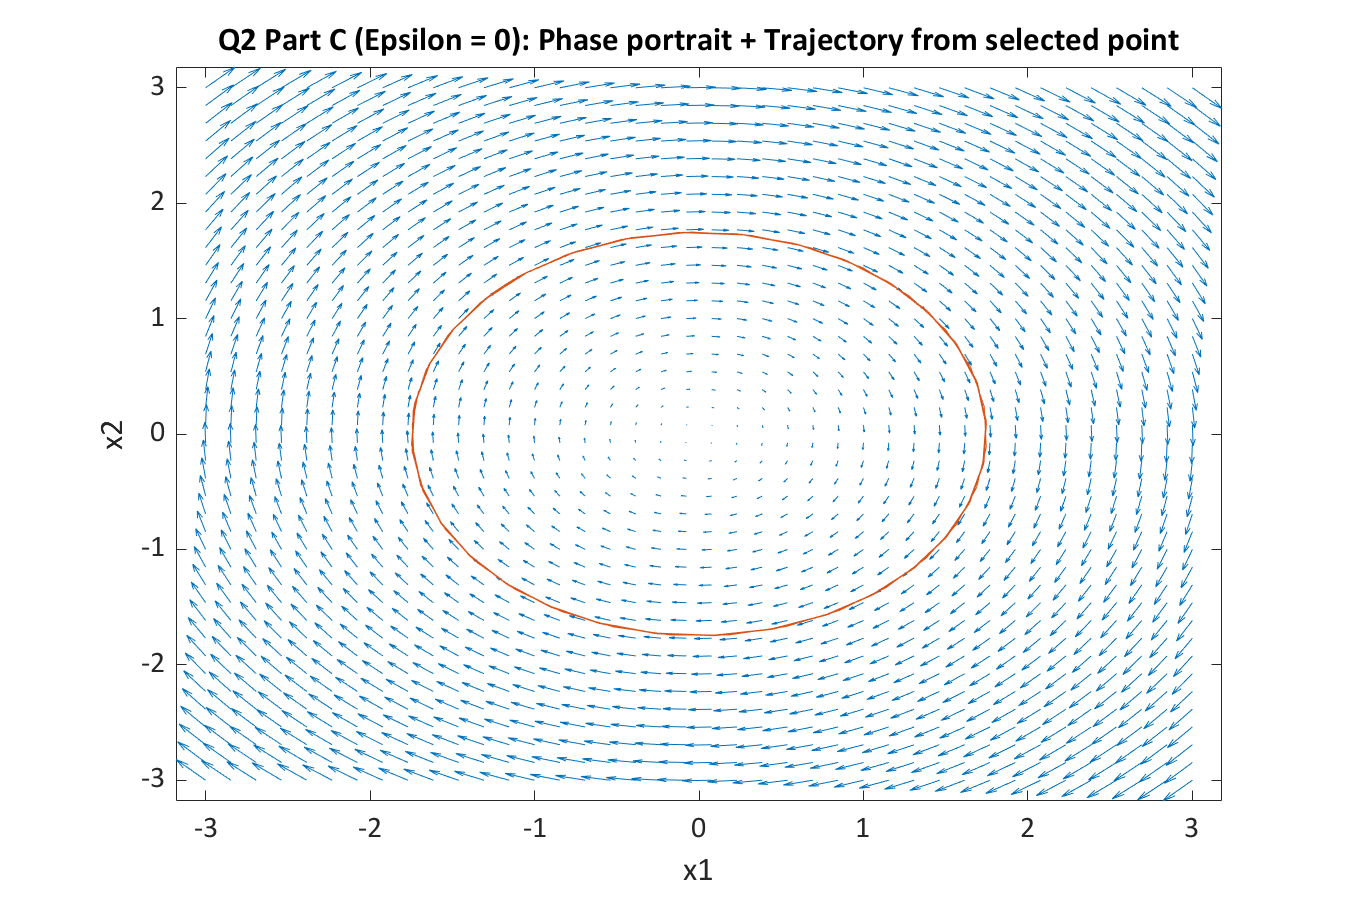

% ONLY ONE POINT CAN BE SELECTED IN ONE RUN!!
% For choosing another point, re-run the script!
epsilon = 0;
fig_q2_eps0_c = figure();
quiver(x1,x2,x1_dot_eps0,x2_dot_eps0,1.2);
fig_q2_eps0_c.Position = [10,10,900,600];
xlabel('x1')
ylabel('x2')
set(gca, 'FontName', 'Calibri', 'FontSize', 15);
axis tight
title('Q2 Part C (Epsilon = 0): Please Click on a point!!')
[a1,b1] = ginput(1);
[t, states_q2_eps0] = ode45(@(t,x)([x(2) ; -x(1)+epsilon.*x(2).*(1-x(1).^2)]), [0 100], [a1;b1]);
hold on;
plot(states_q2_eps0(:,1), states_q2_eps0(:,2));
hold off;
title('Q2 Part C (Epsilon = 0): Phase portrait + Trajectory from selected point')

**QUESTION-2(c) epsilon=1**

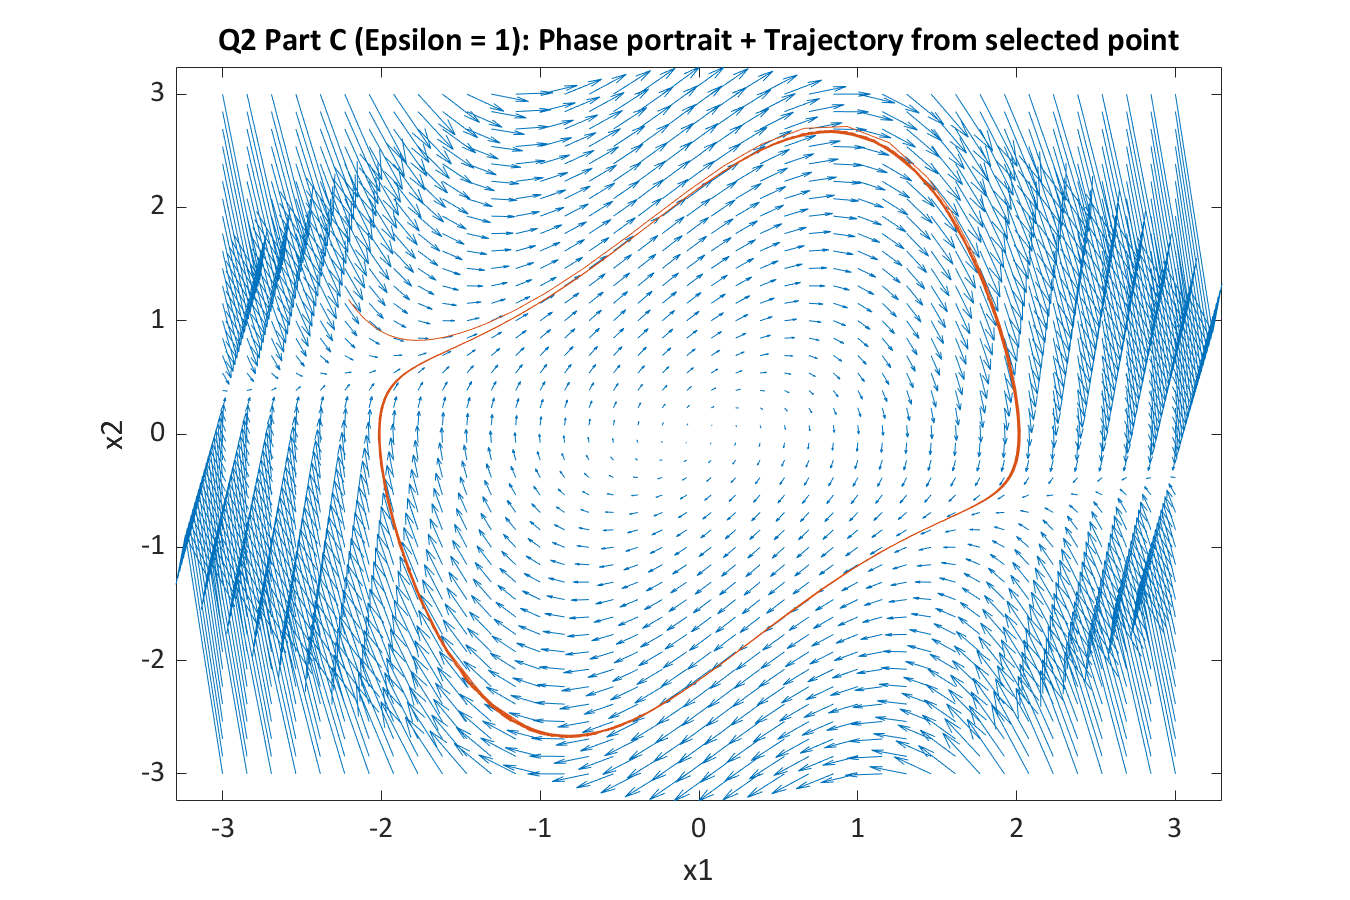

epsilon = 1;
fig_q2_eps1_c = figure();
quiver(x1,x2,x1_dot_eps1,x2_dot_eps1,10);  %Arrows magnified by 10 times
fig_q2_eps1_c.Position = [10,10,900,600];
xlabel('x1')
ylabel('x2')
set(gca, 'FontName', 'Calibri', 'FontSize', 15);
axis tight
title('Q2 Part C (Epsilon = 1): Please Click on a point!!')
[a1,b1] = ginput(1);
[t, states_q2_eps1] = ode45(@(t,x)([x(2) ; -x(1)+epsilon.*x(2).*(1-x(1).^2)]), [0 100], [a1;b1]);
hold on;
plot(states_q2_eps1(:,1), states_q2_eps1(:,2));
hold off;
title('Q2 Part C (Epsilon = 1): Phase portrait + Trajectory from selected point')

**QUESTION-3**

**QUESTION-3(a)**

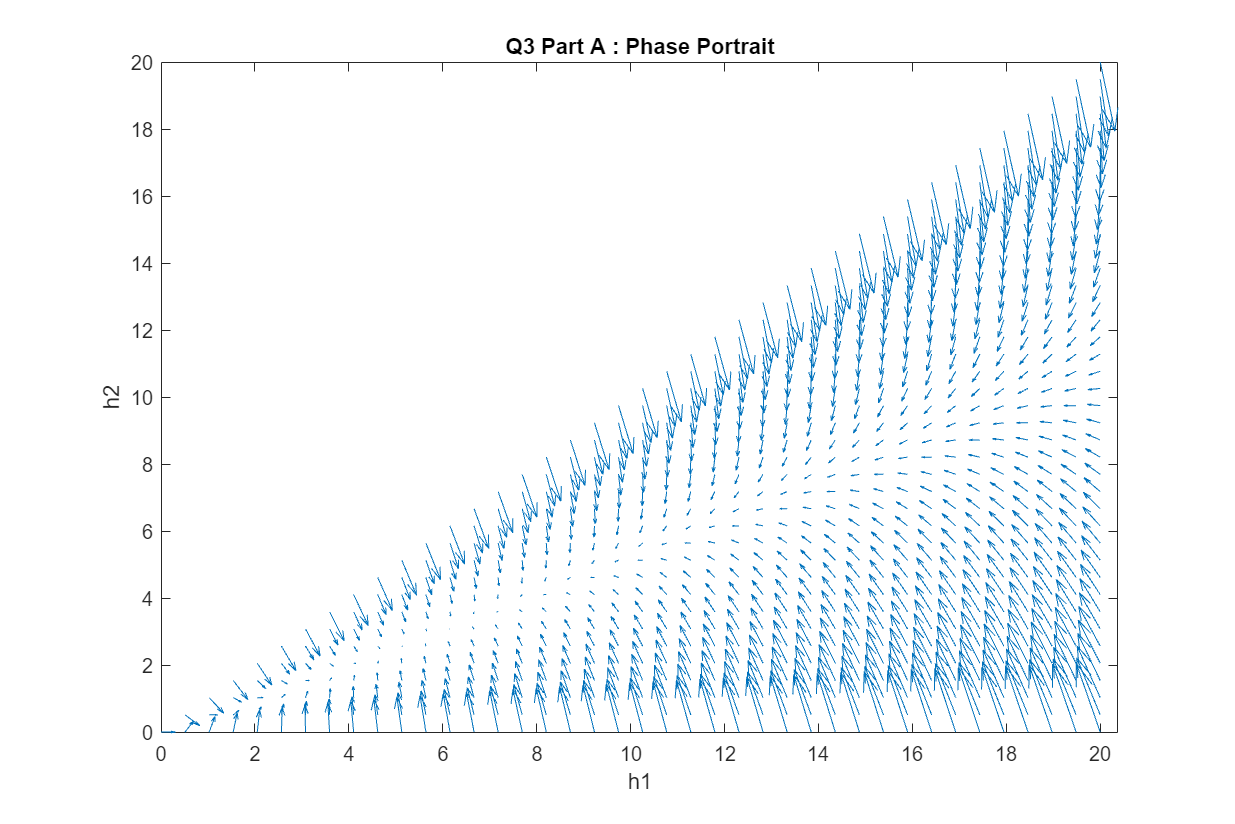

% Parameters 

a1 = 2.0e-3;
a2 = 2.0e-3;

A1 = 0.25;
A2 = 0.10; 
g = 9.8;

qi = 15e-3; % Control input


% Preparing the mesh for phase portrait
step_size = 40 ;
[h1, h2] = meshgrid(linspace(0, 20, step_size) , linspace(0, 20, step_size));
% Finding the derivatives of the states at each point of the mesh %
h1_dot = (qi/A1) - a1*(sqrt(2*g*(h1-h2)))/A1;  %derivatives of state1 (x1_dot)
h2_dot = a1*(sqrt(2*g*(h1-h2)))/A2 - a2*(sqrt(2*g*h2))/A2 ;  %derivatives of state2 (x2_dot)

% Replacing the imaginary (hence invalid!) derivatives for h1<h2 by 0 ! 
for i=1:40
    for j=1:40
        if ~isreal(h1_dot(i,j))
            h1_dot(i,j)=0;
        end
        if ~isreal(h2_dot(i,j))
            h2_dot(i,j)=0;
        end
    end
end


% Plotting the phase portrait %
fig_q3_part_a = figure();

quiver(h1, h2,h1_dot,h2_dot,3);  %Arrows magnified by 10 times
fig_q3_part_a.Position = [10,10,900,600];
title('Q3 Part A : Phase Portrait')
xlabel('h1')
ylabel('h2')
%set(gca, 'FontName', 'Calibri', 'FontSize');
axis tight

**QUESTION-3(b)**

syms a1 a2 A1 A2
h1 = 3; h2 = 1.5; %given heights

q1 = 15e-3; %control input

h1_dot_sym = (qi/A1) - a1*(sqrt(2*g*(h1-h2)))/A1;
h2_dot_sym = a1*(sqrt(2*g*(h1-h2)))/A2 - a2*(sqrt(2*g*h2))/A2;
fprintf("h1_dot = ")

h1_dot = 

disp(simplify(h1_dot_sym))

$$-\frac{280\,\sqrt{15}\,a_{1}-3}{200\,A_{1}}$$

fprintf("h2_dot = ")

h2_dot = 

disp(simplify(h2_dot_sym))

$$\frac{\sqrt{15}\,\left(7\,a_{1}-7\,a_{2}\right)}{5\,A_{2}}$$

**Case 1: Stable**

If both h1_dot and h2_dot are negative, then both the heights would continue to diminish and with time approach zero. Therefore, **If (h1_dot<0 AND h2_dot<0) => System is STABLE.**

From the above symbolic equations: 

    From h1_dot<0 => a1>3/(280*sqrt(15)) => a1> 0.0028

    From h2_dot <0 =>7a1 - 7a2 < 0 => a1 > a2

Therefore condition for **stability** =>  **a2>a1>0.0028**

**Case 2: Unstable**

If either h1_dot or h2_dot are positive, then the hieghts would continue to grow and with time reach infinity. Therefore, **If (h1_dot>0 OR h2_dot>0) => System is UNSTABLE.**

From the above symbolic equations: 

    From h1_dot>0 => a1<3/(280*sqrt(15)) => a1< 0.0028

    From h2_dot>0 =>7a1 - 7a2 > 0 => a1 < a2

Therefore condition for **instability** =>  **Either** **a1>0.0028  OR  a1>a2**

**FUNCTION DECLARATIONS(if needed has to be declared only at the end of the .mlx script)**

function Vinput = V_inp_q1(t,q_part)
    % Control input for question 1
    if q_part=="a"
        % Input voltage for part A of Q1
        Vinput = 20;
    elseif q_part=="b"
        % Input Voltage for part B of Q1
        if t>=2
            Vinput = 20;
        else
            Vinput = 0;
        end
    end
end

function Tload = Tload_q1(t,q_part)
    % Control input for question 1
    if q_part=="a"
        % Load torque for part A of Q1
        Tload = 0;
    elseif q_part=="b"
        % Load torque for part B of Q1
        if t>=30
            Tload=5;
        else
            Tload=0;
        end
    end
end

%submitted by Shreyansh